# Urban Link and Coverage Analysis Using Ray Tracing

关于天线极化的例子可以阅读：https://www.zhihu.com/question/445395192

This example shows how to use ray tracing to analyze communication links and coverage areas in an urban environment. 

Within the example:

- Import and visualize 3-D buildings data into Site Viewer

- Define a transmitter site and ray tracing propagation model corresponding to a 5G urban scenario

- Analyze a link in non-line-of-sight conditions

- Visualize coverage using the shooting and bouncing rays (SBR) ray tracing method with different numbers of reflections, diffractions, and launched rays

The example requires one of these products: Antenna Toolbox™ or Communications Toolbox™.

Optional Product: This example also shows you how to use Phased Array System Toolbox™ to optimize a non-line-of-sight link using beam steering.

## Import and Visualize Buildings Data

Import an OpenStreetMap® file (`.osm`) corresponding to Canary Wharf in London, UK. The file was downloaded from [https://www.openstreetmap.org](https://www.openstreetmap.org/), which provides access to crowd-sourced map data all over the world. The data is licensed under the Open Data Commons Open Database License (ODbL), [https://opendatacommons.org/licenses/odbl/](https://opendatacommons.org/licenses/odbl/). The buildings information contained within the OpenStreetMap file is imported and visualized in Site Viewer.

viewer = siteviewer(Buildings="canarywharf.osm",Basemap="topographic");

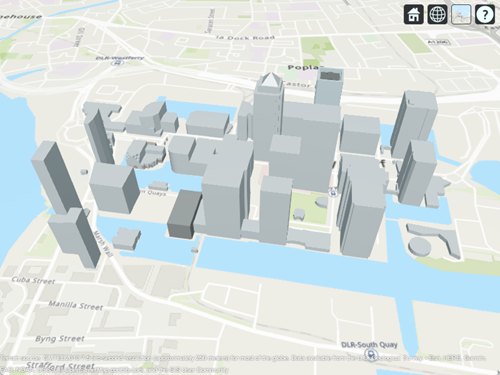

## **Define Transmitter Site**

Define a transmitter site to model a small cell scenario in a dense urban environment. The transmitter site represents a base station that is placed on a pole servicing the surrounding area which includes a neighboring park. The transmitter uses the default isotropic antenna (全向天线), and operates at a carrier frequency of 28 GHz with a power level of 5 W.

tx = txsite(Name="Small cell transmitter", ...
    Latitude=51.50375, ...
    Longitude=-0.01843, ...
    AntennaHeight=10, ...
    TransmitterPower=5, ...
    TransmitterFrequency=28e9);
show(tx)

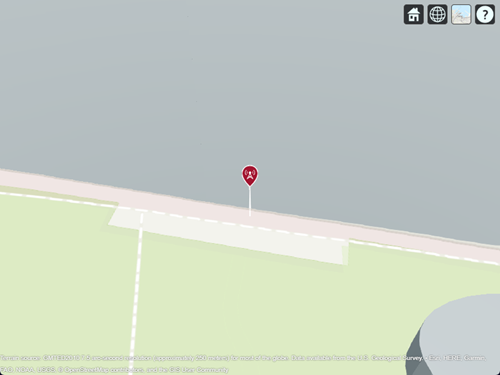

## View Coverage Map for Line-of-Sight Propagation

Create a ray tracing propagation model using the shooting and bouncing rays (SBR) method. The SBR propagation model uses ray tracing analysis to compute propagation paths and their corresponding path losses. Path loss is calculated from free-space loss, reflection and diffraction loss (衍射损耗) due to interactions with materials, and antenna polarization loss (天线计划损失). 

Limit the initial analysis to only line-of-sight propagation paths by setting the maximum number of reflections to 0. Set the building and terrain material types to model perfect electrical conductors.

rtpm = propagationModel("raytracing", ...
    Method="sbr", ...
    MaxNumReflections=0, ...
    BuildingsMaterial="perfect-reflector", ...
    TerrainMaterial="perfect-reflector");

View the corresponding coverage map for a maximum range of 250 meters from the base station. The coverage map shows received power for a receiver at each ground location but is not computed for building tops or sides (建筑物顶部或侧面).

coverage(tx,rtpm, ...
    SignalStrengths=-120:-5, ...
    MaxRange=250, ...
    Resolution=3, ...
    Transparency=0.6)

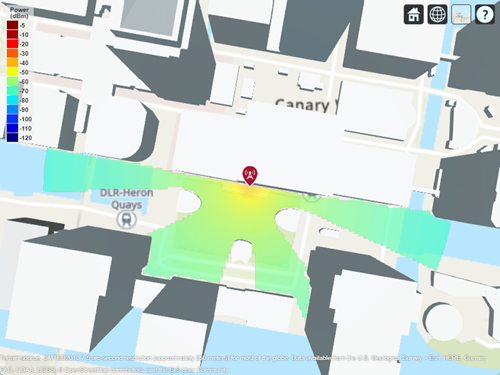

## Define Receiver Site in Non-Line-of-Sight Location

The coverage map for line-of-sight propagation shows shadowing due to obstructions. Define a receiver site to model a mobile receiver in an obstructed location. Plot the line-of-sight path to show the obstructed path from the transmitter to the receiver.

rx = rxsite(Name="Small cell receiver", ...
    Latitude=51.50216, ...
    Longitude=-0.01769, ...
    AntennaHeight=1);

los(tx,rx)

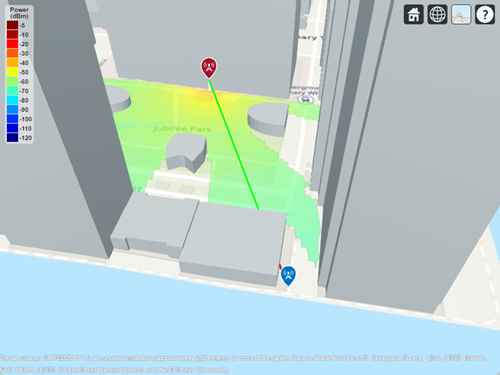

## Plot Propagation Path Using Ray Tracing

Adjust the ray tracing propagation model to include single-reflection paths, then plot the rays. The result shows signal propagation along a single-reflection path. View the corresponding propagation characteristics, including the received power, phase change, distance, and angles of departure and arrival (出发角和到达角), by clicking on the plotted path.

rtpm.MaxNumReflections = 1;
clearMap(viewer)
raytrace(tx,rx,rtpm)

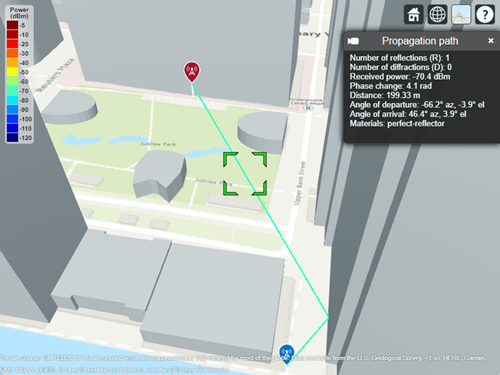

## Analyze Signal Strength and Effect of Materials

Compute the received power.

ss = sigstrength(rx,tx,rtpm);
disp("Received power using perfect reflection: " + ss + " dBm")

Received power using perfect reflection: -70.392 dBm


Update the model to use concrete for the buildings and terrain materials. Then, update the rays shown in Site Viewer.

rtpm.BuildingsMaterial = "concrete";
rtpm.TerrainMaterial = "concrete";
raytrace(tx,rx,rtpm)

Recalculate the received power. The use of realistic material reflection results in approximately 8 dB of loss compared to perfect reflection.

ss = sigstrength(rx,tx,rtpm);
disp("Received power using concrete materials: " + ss + " dBm")

Received power using concrete materials: -78.5467 dBm


## Include Weather Loss

Adding weather impairments to the propagation model and re-computing the received power results in another 1.5 dB of loss.

rtPlusWeather = ...
    rtpm + propagationModel("gas") + propagationModel("rain");
raytrace(tx,rx,rtPlusWeather)

ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power including weather loss: " + ss + " dBm")

Received power including weather loss: -80.064 dBm


## Plot Propagation Paths Including Two Reflections

Expand the point-to-point analysis to include two-reflection paths and choose a smaller angular separation between launched rays (发射射线之间的角度间隔) for the SBR method. The visualization shows two clusters of propagation paths. The total received power for two-reflection paths is similar to the total received power for single-reflection paths.

rtPlusWeather.PropagationModels(1).MaxNumReflections = 2;
rtPlusWeather.PropagationModels(1).AngularSeparation = "low";

ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power with two-reflection paths: " + ss + " dBm")

Received power with two-reflection paths: -79.7388 dBm


clearMap(viewer)
raytrace(tx,rx,rtPlusWeather)

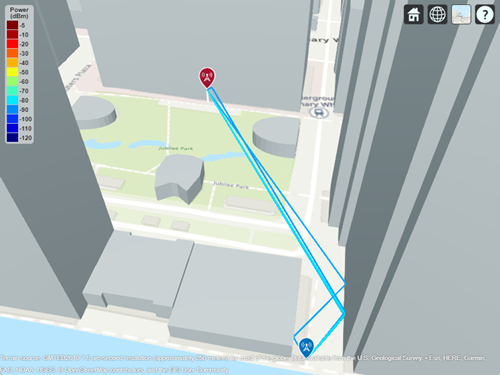

## Plot Propagation Paths Including Two Reflections and One Diffraction (衍射)

Expand the point-to-point analysis to include paths with one edge diffraction. The visualization shows the two stronger clusters of propagation paths due to reflections with no diffraction, plus weaker clusters involving one diffraction. The total received power is not changed significantly by the inclusion of one diffraction.

rtPlusWeather.PropagationModels(1).MaxNumDiffractions = 1;

ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power with two-reflection and one-diffraction paths: " + ss + " dBm")

Received power with two-reflection and one-diffraction paths: -79.9061 dBm


raytrace(tx,rx,rtPlusWeather)

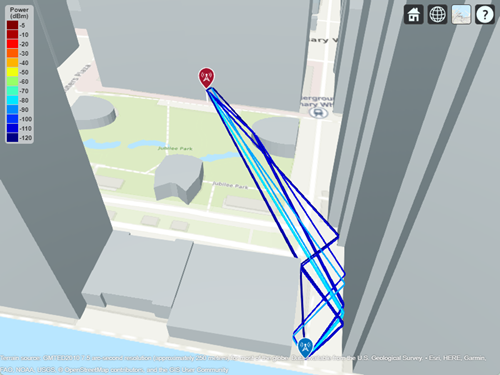

## View Coverage Map with Single-Reflection Paths

Use the configured propagation model and generate a coverage map that includes single-reflection paths and weather impairments.

rtPlusWeather.PropagationModels(1).MaxNumReflections = 1;
rtPlusWeather.PropagationModels(1).MaxNumDiffractions = 0;
clearMap(viewer)
show(tx)

coverage(tx,rtPlusWeather, ...
    SignalStrengths=-120:-5, ...
    MaxRange=250, ...
    Resolution=2, ...
    Transparency=0.6)

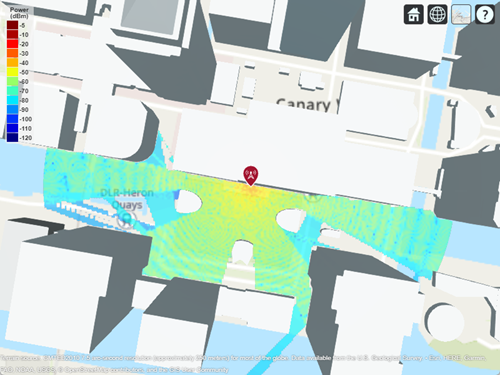

## View Coverage Map with Two Reflections and One Diffraction

Account for more propagation paths by increasing the maximum number of reflections and diffractions for the ray tracing analysis to 2 and 1, respectively. Decrease the number of launched rays as a trade-off.

rtPlusWeather.PropagationModels(1).MaxNumReflections = 2;
rtPlusWeather.PropagationModels(1).MaxNumDiffractions = 1;
rtPlusWeather.PropagationModels(1).AngularSeparation = "high";
clearMap(viewer)

Plot the coverage map using precalculated results contained in a MAT-file. You can also generate the coverage results using the commented code. Depending on the computer hardware, the commented code can take several hours to run.

show(tx)

load("coverageResultsTwoRefOneDiff.mat");
contour(coverageResultsTwoRefOneDiff, ...
    Type="power", ...
    Transparency=0.6)

% coverage(tx,rtPlusWeather, ...
%     SignalStrengths=-120:-5, ...
%     MaxRange=250, ...
%     Resolution=2, ...
%     Transparency=0.6)

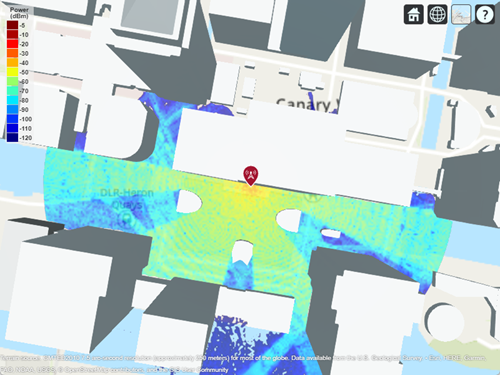

## Further Exploration: Use Beam Steering to Enhance Received Power

Many modern communications systems use techniques to steer (引导) the transmitter antenna to achieve optimal link quality. This section uses Phased Array System Toolbox™ to optimally steer a beam to maximize received power for a non-line-of-sight link.

Define a custom antenna from Report ITU-R M.2412 [1] for evaluating 5G radio technologies. Create an 8-by-8 uniform rectangular array with half-wavelength element spacing using the pattern defined in Section 8.5 of the report.

azvec = -180:180; % Azimuth angles (方位角) (deg)
elvec = -90:90; % Elevation angles (仰角) (deg)
SLA = 30; % Maximum side-lobe level attenuation 最大旁瓣电平衰减 (dB)
tilt = 0; % Tilt angle (倾斜角) (deg)
az3dB = 65; % 3 dB beamwidth in azimuth (deg)
el3dB = 65; % 3 dB beamwidth in elevation (deg)
lambda = physconst("lightspeed")/tx.TransmitterFrequency; % Wavelength (m)

[az,el] = meshgrid(azvec,elvec);
azMagPattern = -min(12*(az/az3dB).^2,SLA);
elMagPattern = -min(12*((el-tilt)/el3dB).^2,SLA);
combinedMagPattern = -min(-(azMagPattern + elMagPattern), ...
    SLA); % Relative antenna gain (dB)

antennaElement = phased.CustomAntennaElement(MagnitudePattern=combinedMagPattern);
tx.Antenna = phased.URA(Size=[8 8], ...
    Element=antennaElement, ...
    ElementSpacing=[lambda/2 lambda/2]);

Calculate the peak directivity (指向性) of the array.

antennaDirectivity = pattern(tx.Antenna, tx.TransmitterFrequency);
antennaDirectivityMax = max(antennaDirectivity(:));
disp("Peak antenna directivity: " + antennaDirectivityMax + " dBi")

Peak antenna directivity: 23.4449 dBi


Point the antenna south and view the radiation pattern.

tx.AntennaAngle = -90;

clearMap(viewer)
show(rx)
pattern(tx,Transparency=0.6)
hide(tx)

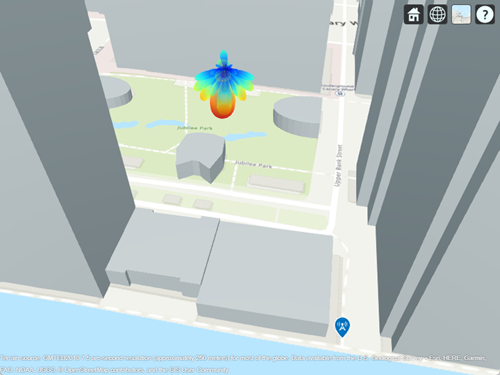

Set the maximum number of reflections to 1 and maximum number of diffractions to 0 to perform analysis on the dominant single-reflection path (主导单反射路径). Call `raytrace` with an output to access the rays that were computed. The returned `comm.Ray` objects include both the geometric and propagation-related characteristics of each ray.

rtPlusWeather.PropagationModels(1).MaxNumReflections = 1;
rtPlusWeather.PropagationModels(1).MaxNumDiffractions = 0;
ray = raytrace(tx,rx,rtPlusWeather);
disp(ray{1})

Get the angle-of-departure (离去角) for the single-reflection path and apply this angle to steer the antenna in the optimal direction to achieve higher received power. The angle-of-departure azimuth (方位角) is offset by the physical antenna angle azimuth to convert it to the steering vector azimuth defined in the local coordinate system of the phased array antenna.

aod = ray{1}.AngleOfDeparture;
steeringaz = wrapTo180(aod(1)-tx.AntennaAngle(1));
steeringVector = phased.SteeringVector(SensorArray=tx.Antenna);
sv = steeringVector(tx.TransmitterFrequency,[steeringaz;aod(2)]);
tx.Antenna.Taper = conj(sv);

Show the antenna energy directed along the propagation path by plotting the radiation pattern. The new received power increases by more than 20 dB. The increased received power corresponds to the peak directivity of the antenna.

pattern(tx,Transparency=0.6)
raytrace(tx,rx,rtPlusWeather);
hide(tx)
    
ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power with beam steering: " + ss + " dBm")

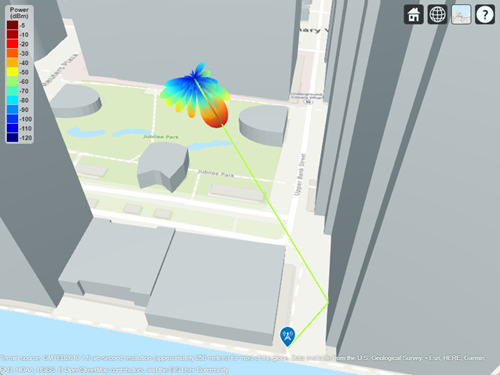

## Conclusion

This example used ray tracing for link and coverage analysis in an urban environment. The analysis shows: 

- How to use ray tracing analysis to predict signal strength for non-line-of-sight links where reflected and edge-diffracted propagation paths exist

- Analysis with realistic materials has a significant impact on the calculated path loss and received power

- Analysis with higher number of reflections and diffractions results in increased computation time but reveals additional areas of signal propagation

- Usage of a directional antenna with beam steering significantly increases the received power for receivers, even if they are in non-line-of-sight locations

This example analyzed received power and path loss for links and coverage. To see how to use ray tracing to configure a channel model for link-level simulation, see the [Indoor MIMO-OFDM Communication Link using Ray Tracing](docid:comm_ug#example-IndoorCommLinkUsingRayTracing) example.

## References

[1] Report ITU-R M.2412, "Guidelines for evaluation of radio interface technologies for IMT-2020", 2017. [https://www.itu.int/pub/R-REP-M.2412](https://www.itu.int/pub/R-REP-M.2412)

*Copyright 2019-2024 The MathWorks, Inc.*